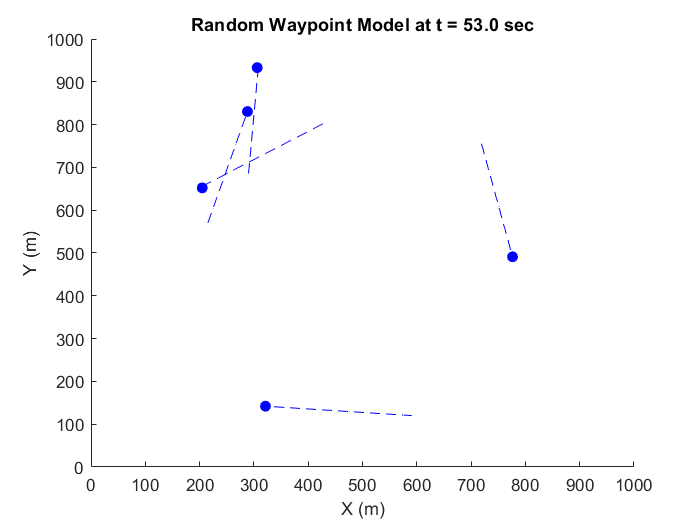


% --- call ---
bsPos = [500, 500];                 % BS at the center of a 1 km × 1 km cell
[SINR1,SINR2,SINR3,SINR4,SINR5,U1,U2,U3,U4,U5] = ...
    calculateControlledSINR2(1000, 2e9, 30, 43, 10e6, 5, bsPos);

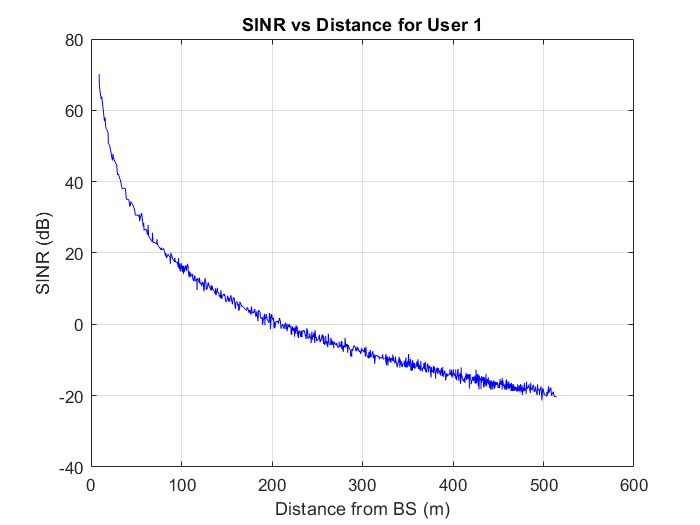


% distance from BS and sorted plot
d1 = vecnorm(U1 - bsPos, 2, 2);
[ds, idx] = sort(d1);               % sort by distance for a clean curve
figure; plot(ds, SINR1(idx), 'b-');
xlabel('Distance from BS (m)'); ylabel('SINR (dB)');
title('SINR vs Distance for User 1'); grid on;

function [S1,S2,S3,S4,S5,U1,U2,U3,U4,U5] = ...
    calculateControlledSINR2(simTime, fc, hBS, txPower, BW, numUsers, bsPos)
    [U1,U2,U3,U4,U5] = randomWaypointSimulation(numUsers, simTime);
    S1 = computeSINR(U1, fc, txPower, BW, bsPos);
    S2 = computeSINR(U2, fc, txPower, BW, bsPos);
    S3 = computeSINR(U3, fc, txPower, BW, bsPos);
    S4 = computeSINR(U4, fc, txPower, BW, bsPos);
    S5 = computeSINR(U5, fc, txPower, BW, bsPos);
end

function SINR_dB = computeSINR(Uepos, fc, txPower, BW, bsPos)
    c = 3e8; k = 1.38e-23; T = 290;
    N = size(Uepos,1);

    % distance from BS (centered)
    d2D = vecnorm(Uepos - bsPos, 2, 2);
    d2D(d2D < 1) = 1;

    % 3GPP UMa NLOS path loss (meters, fc in GHz)
    pathLoss_dB = 28 + 50*log10(d2D) + 20*log10(fc/1e9);

    % lognormal shadowing + smoothed Rayleigh
    shadowing_dB = 0.9*randn(N,1);
    fading_linear = (raylrnd(1,N,1)).^2;
    fading_dB = 10*log10(movmean(fading_linear, 200));

    totalLoss_dB = pathLoss_dB + shadowing_dB - fading_dB;

    tx_W = 10^((txPower-30)/10);
    rx_W = tx_W ./ 10.^(totalLoss_dB/10);
    noise_W = k*T*BW;

    SINR_dB = 10*log10(rx_W./noise_W);
end
function varargout = randomWaypointSimulation(numUsers,simTime)
    % Simulation Parameters
    %numUsers = 5;              % Number of users
    areaSize = 1000;            % Area size (square: areaSize x areaSize)
    %simTime = 100;             % Total simulation time in seconds
    dt = 1;                    % Time step in seconds
        
    pauseTime = 0;             % Pause time at each waypoint (seconds)
    
    % Initialize user state
    users(numUsers) = struct();
    for i = 1:numUsers
        users(i).pos = areaSize * rand(1,2);    % Initial position
        users(i).dest = areaSize * rand(1,2);   % First destination
        users(i).speed = 5;
        users(i).pause = 0;                     % Pause counter
        users(i).trajectory = users(i).pos;     % Store path
    end

    % Simulation loop
    for t = 0:dt:simTime
        clf;
        hold on;
        axis([0 areaSize 0 areaSize]);
        title(sprintf('Random Waypoint Model at t = %.1f sec', t));
        xlabel('X (m)');
        ylabel('Y (m)');
        
        for i = 1:numUsers
            user = users(i);
            if user.pause > 0
                user.pause = user.pause - dt;
            else
                direction = user.dest - user.pos;
                distanceToDest = norm(direction);
                if distanceToDest < user.speed * dt
                    user.pos = user.dest;
                    user.dest = areaSize * rand(1,2);
                    user.speed = 5;
                    user.pause = pauseTime;
                else
                    user.pos = user.pos + (user.speed * dt) * (direction / distanceToDest);
                end
            end
            user.trajectory(end+1, :) = user.pos;
            users(i) = user;

            % Plot user
            plot(user.pos(1), user.pos(2), 'bo', 'MarkerSize', 6, 'MarkerFaceColor', 'b');
            plot(user.trajectory(:,1), user.trajectory(:,2), 'b--');
        end
        
        drawnow;
        pause(0.001);  % for animation
    end
    for i=1:numUsers
        varargout{i}=users(i).trajectory(3:end,:);
    end
end